%finding the total area of a converging series
a = 1;
r = 1/4;

%in a converging series -1<r<1
total_area = a/(1-r)

total_area = 1.3333

%calculating the series 20 values individually
n_value = 1:20;

n_value =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


series = zeros(1,20);
series(1) = a;

for i=2:20;
    series(i) = series(i-1) + a*r^(i-1);
end

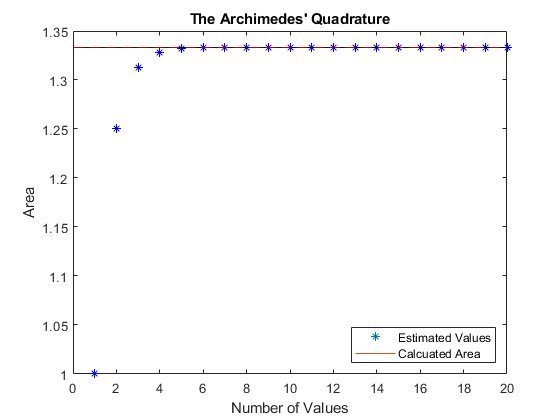

%ploting the series with the 20 value approx and calculated area
plot(n_value,series,"*b")
hold on
yline(total_area,"r--")
title("The Archimedes' Quadrature")
ylabel("Area")
xlabel("Number of Values")
legend("Estimated Values", "Calcuated Area", 'location', 'southeast')